Problem 1

dE/dt = -k1E*S + (k-1 + k2)*c

dS/dt = -k1E*S + k-1*c

dc/dt = k1E*S - (k-1 + k2)*c

dP/dt = k2*c

Problem 2


----------Running MM Script-----------

Intial substrate: 1.000000
Initial Enzyme: 1.000000

KM: 0.202000
Fast time tc: 0.001387
Slow time ts: 1.001667

tc/ts= 0.001384

epsilon=e0/(KM+s0): 0.831947



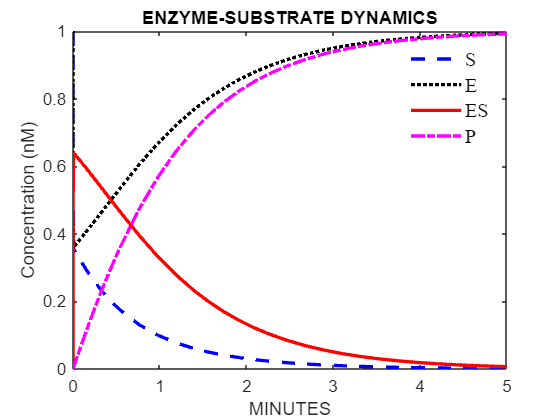

enzymkin

Problem 3

dS/dt = -(k2*e0*S) / (S + km)

dc/dt = 0

dP/dt = (k2*e0*S) / (S + km)

km = (k-1 + k2) / k1

c_qssa = (e0*S) / (S + km)

p_qssa = (k2*e0*S) / (S + km)

s_qssa = -(k2*e0*S) / (S + km)

e(t) = 1 -  (e0*S) / (S + km)

K1      = 10;  
K1MINUS = 200;  
K2      = 1.2;  

% Initial conditions x0.
s0 = 1; 
e0 = 1; 
c0 = 0;
p0 = 0;
s_qssa = 1;
p_qssa = 0;

% First 4 elements are for the original set of equations
% Last 2 elements are for sQSSA. 
% [s_ori e_ori c_ori p_ori s_qssa p_qssa]
x0 = [s0; e0; c0; p0; s_qssa; p_qssa];  % ICs 

% Calculate QSSA metrics
Km = (K1MINUS+K2)./K1;
tc = 1./(K1*(s0+Km));
ts = (s0+Km)./(e0*K2);
epsilon = e0/(Km+s0);

disp(sprintf('\n----------Running MM Script-----------\n'));


----------Running MM Script-----------



disp(sprintf('Intial substrate: %f\nInitial Enzyme: %f\n',s0,e0));

Intial substrate: 1.000000
Initial Enzyme: 1.000000



disp(sprintf('KM: %f\nFast time tc: %f\nSlow time ts: %f\n',Km,tc,ts));

KM: 20.120000
Fast time tc: 0.004735
Slow time ts: 17.600000



disp(sprintf('tc/ts= %f\n',tc/ts));

tc/ts= 0.000269



disp(sprintf('epsilon=e0/(KM+s0): %f\n',epsilon));

epsilon=e0/(KM+s0): 0.047348



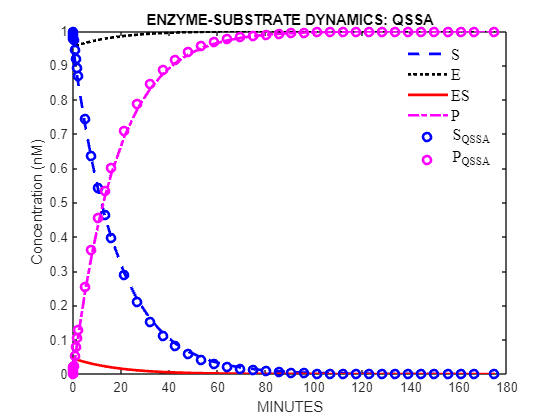


% Call Matlab Numerical Solver on our function f(t,x)
tspan = [0 floor(10*ts)]; %scale simulation time to slow time
[t,x]=ode15s(@(t,x) QSSA_func(t,x,K1,K1MINUS,K2,e0,Km), tspan, x0);

% Post Process
h = plot(t,x);

set(h,{'LineWidth'},{2;2;2;2;2;2},{'LineStyle'},...
    {'--';':';'-';'-.';'none';'none'},{'Marker'},{'none';'none';'none';'none';'o';'o'},{'Color'},{'b';'k';'r';'m';'b';'m'});
title(sprintf('ENZYME-SUBSTRATE DYNAMICS: QSSA'));
xlabel('MINUTES');
ylabel('Concentration (nM)');
legend({'S','E','ES','P','S_{QSSA}','P_{QSSA}'},'FontName','Times','FontSize',12);
legend('boxoff')

Problem 4

K1      = 600;  
K1MINUS = 120;  
K2      = 1.2; 

% Calculate QSSA metrics
Km = (K1MINUS+K2)./K1;
tc = 1./(K1*(s0+Km));
ts = (s0+Km)./(e0*K2);
epsilon = e0/(Km+s0);

disp(sprintf('\n----------Running MM Script-----------\n'));


----------Running MM Script-----------



disp(sprintf('Intial substrate: %f\nInitial Enzyme: %f\n',s0,e0));

Intial substrate: 1.000000
Initial Enzyme: 1.000000



disp(sprintf('KM: %f\nFast time tc: %f\nSlow time ts: %f\n',Km,tc,ts));

KM: 0.202000
Fast time tc: 0.001387
Slow time ts: 1.001667



disp(sprintf('tc/ts= %f\n',tc/ts));

tc/ts= 0.001384



disp(sprintf('epsilon=e0/(KM+s0): %f\n',epsilon));

epsilon=e0/(KM+s0): 0.831947



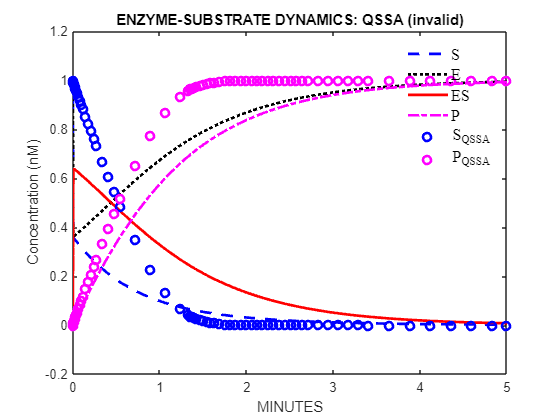


% Call Matlab Numerical Solver on our function f(t,x)
tspan = [0 floor(5*ts)]; %scale simulation time to slow time
[t,x]=ode15s(@(t,x) QSSA_func(t,x,K1,K1MINUS,K2,e0,Km), tspan, x0);

% Post Process
h = plot(t,x);

set(h,{'LineWidth'},{2;2;2;2;2;2},{'LineStyle'},...
    {'--';':';'-';'-.';'none';'none'},{'Marker'},{'none';'none';'none';'none';'o';'o'},{'Color'},{'b';'k';'r';'m';'b';'m'});
title(sprintf('ENZYME-SUBSTRATE DYNAMICS: QSSA (invalid)'));
xlabel('MINUTES');
ylabel('Concentration (nM)');
legend({'S','E','ES','P','S_{QSSA}','P_{QSSA}'},'FontName','Times','FontSize',12);
legend('boxoff')


K1      = 10;  
K1MINUS = 200;  
K2      = 1.2;  

% Calculate QSSA metrics
Km = (K1MINUS+K2)./K1;
tc = 1./(K1*(s0+Km));
ts = (s0+Km)./(e0*K2);
epsilon = e0/(Km+s0);

disp(sprintf('\n----------Running MM Script-----------\n'));


----------Running MM Script-----------



disp(sprintf('Intial substrate: %f\nInitial Enzyme: %f\n',s0,e0));

Intial substrate: 1.000000
Initial Enzyme: 1.000000



disp(sprintf('KM: %f\nFast time tc: %f\nSlow time ts: %f\n',Km,tc,ts));

KM: 20.120000
Fast time tc: 0.004735
Slow time ts: 17.600000



disp(sprintf('tc/ts= %f\n',tc/ts));

tc/ts= 0.000269



disp(sprintf('epsilon=e0/(KM+s0): %f\n',epsilon));

epsilon=e0/(KM+s0): 0.047348



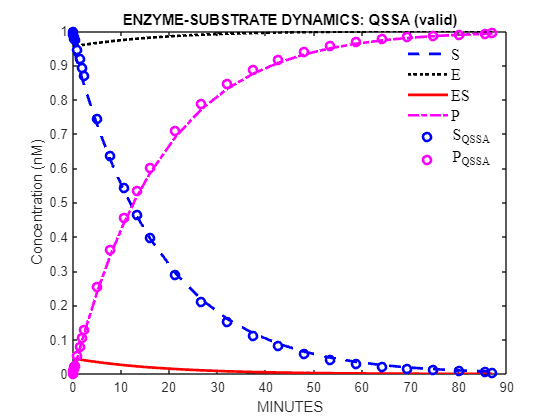


% Call Matlab Numerical Solver on our function f(t,x)
tspan = [0 floor(5*ts)]; %scale simulation time to slow time
[t,x]=ode15s(@(t,x) QSSA_func(t,x,K1,K1MINUS,K2,e0,Km), tspan, x0);

% Post Process
h = plot(t,x);

set(h,{'LineWidth'},{2;2;2;2;2;2},{'LineStyle'},...
    {'--';':';'-';'-.';'none';'none'},{'Marker'},{'none';'none';'none';'none';'o';'o'},{'Color'},{'b';'k';'r';'m';'b';'m'});
title(sprintf('ENZYME-SUBSTRATE DYNAMICS: QSSA (valid)'));
xlabel('MINUTES');
ylabel('Concentration (nM)');
legend({'S','E','ES','P','S_{QSSA}','P_{QSSA}'},'FontName','Times','FontSize',12);
legend('boxoff')

QSSA is valid if E0 << Km + S0, or if Km is much larger than 1. This is evident in the two plots, where in the first plot, Km = .202. In this case, S_QSSA and P_QSSA barely followed the growth of S and P, respectively. However, in the second plot where Km = 20.12, S_QSSA and P_QSSA aligned with S and P, respectively. This indicates that QSSA is valid if Km is large, or if K-1 + K2 > K1. This makes sense, as the rate from substrate + enzyme to complex should be small given that dc/dt = 0, and the rate of production of products and substrate should be fast.

Functions

function [dxdt] = QSSA_func(t,x,K1,K1MINUS,K2,e0,Km)
% Single Substrate-Enzyme Reaction
% R1: S + E -- k1 --> ES
% R2: ES    -- k1minus --> E + S 
% R3: ES    -- k2 --> E + P 

% ----Original----
s=x(1); e=x(2); c=x(3); p=x(4);
dsdt = -K1*e*s + K1MINUS*c;      
dedt = -K1*e*s + (K1MINUS + K2)*c;  
dcdt = K1*e*s - (K1MINUS + K2)*c;   
dpdt = K2*c;      

% ----sQSSA----
% Constraints
%     e(t) + c(t) = e0
% Assumption
%     dcdt ~ 0
s_qssa = x(5); 
dp_dt = (K2*e0*s_qssa)./(s_qssa+Km);
ds_dt = -dp_dt;

% Pack output
dxdt=[dsdt;dedt;dcdt;dpdt;ds_dt;dp_dt];
end